clear
format shortG

syms c x F_0 omega t k m

syms x(t)

x_1 = diff(x(t), t)

$$x\_1 = \frac{\partial }{\partial t}x\left(t\right)$$


x_2 = diff(x_1, t)

$$x\_2 = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$


disp('Uden ydre kraft')

Uden ydre kraft


displayFormula('0 == x_2 + c/m * x_1 + k/m * x')

$$0=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{c}{m}\,\frac{\partial }{\partial t}x\left(t\right)+\frac{k}{m}\,x\left(t\right)$$


disp('Med ydre kraft')

Med ydre kraft



displayFormula('F_0 * sin(omega * t) / m == x_2 + c/m * x_1 + k/m * x')

$$\frac{F_{0}\,\sin\left(\omega \,t\right)}{m}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+\frac{c}{m}\,\frac{\partial }{\partial t}x\left(t\right)+\frac{k}{m}\,x\left(t\right)$$

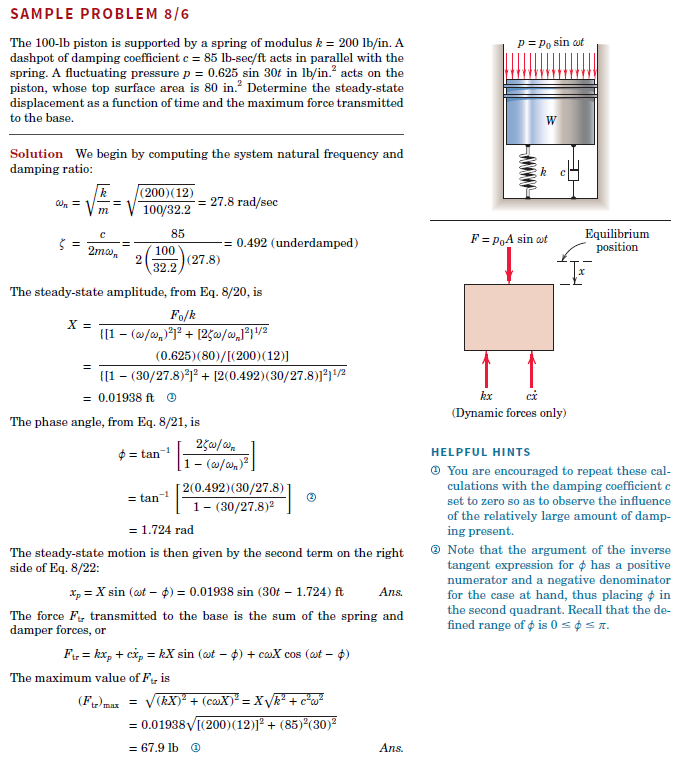

Hvor det kan indses at 


$$F = m*a \\
a = \ddot{x} = F/m$$



clear
k = 35 *10^3; %N/m   % fjeder modulus
m = 45; %kg          %massen af emnet
c = 1250;% N*s / m   %dæmpnings konstanten
omega = 30; %1/s     %drivnings frekvensen
p_0 = 4000; %pa      %tryk pr areal

A = 0.050; % m^2 % tryk areal

syms t

disp('Kraften på emnet')

Kraften på emnet


F = p_0 * A * sin(omega * t)

$$F = 200\,\sin\left(30\,t\right)$$


disp('Egensvingningen findes')

Egensvingningen findes


omega_n = sqrt(k/m) %egensvingningen

omega_n = 27.8887


disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * omega_n) % viscous damping factor or damping ratio

zeta = 0.4980


if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er underdamped



disp('Aplituden findes')

Aplituden findes


X = (F / k) / sqrt( (1 - (omega / omega_n)^2 )^2 + (2 * zeta * omega / omega_n)^2 )

$$X = \frac{\sqrt{2}\,\sqrt{17}\,\sin\left(30\,t\right)}{1105}$$


disp('Phase vinklen findes')

Phase vinklen findes


phi = atan((2 * zeta * omega / omega_n)/ (1 - (omega/omega_n)^2 ))

phi = -1.4252


disp('Forskydningen findes nu med ligning 8/22 til') 

Forskydningen findes nu med ligning 8/22 til


x_p = X * sin(omega * t - phi);
x_p_ = vpa(x_p, 3)

$$x\_p\_ = 0.00528\,\sin\left(30.0\,t+1.43\right)\,\sin\left(30.0\,t\right)$$


disp('Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag')

Vi finder den afledet af forskydningsligninen så vi kan findes dæmperens bidrag


x_p_1 = diff(x_p, t)

$$x\_p\_1 = \frac{6\,\sqrt{2}\,\sqrt{17}\,\cos\left(30\,t\right)\,\sin\left(30\,t+\frac{6418385831555115}{4503599627370496}\right)}{221}+\frac{6\,\sqrt{2}\,\sqrt{17}\,\sin\left(30\,t\right)\,\cos\left(30\,t+\frac{6418385831555115}{4503599627370496}\right)}{221}$$


disp('Kraften overført til gulvet er summen af fjeder og dæmper')

Kraften overført til gulvet er summen af fjeder og dæmper


F_tr = k*x_p + c*x_p_1;
F_tr_ = vpa(F_tr, 3)

$$F\_tr\_ = 198.0\,\cos\left(30.0\,t+1.43\right)\,\sin\left(30.0\,t\right)+198.0\,\sin\left(30.0\,t+1.43\right)\,\cos\left(30.0\,t\right)+185.0\,\sin\left(30.0\,t+1.43\right)\,\sin\left(30.0\,t\right)$$


disp('Den maximale kraft findes hvor sin ledet er 1')

Den maximale kraft findes hvor sin ledet er 1


F_tr_max = X * sqrt(k^2 + c^2 * omega^2);
F_tr_max_ = vpa(F_tr_max, 3)

$$F\_tr\_max\_ = 271.0\,\sin\left(30.0\,t\right)$$


F_tr_max_final = 271.0

F_tr_max_final = 271

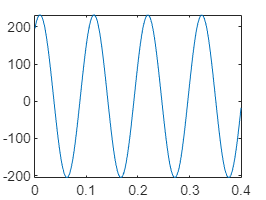


fplot(F_tr, [0,0.4])

 8/38

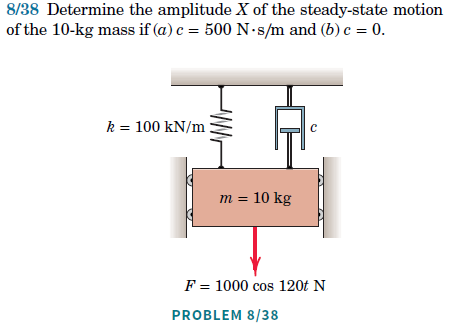

8/39, 8/42, (8/56), (8/53), (8/44), (8/46), (8/55),